clear

%ManivelaBiela=readtable("MatLab cinetica\Reacciones biela\A3-manivela-biela.txt","Delimiter"," ");
%ManivelaBiela=readtable("MatLab cinetica\Reacciones biela\B3-manivela-biela.txt","Delimiter"," ");
ManivelaBiela=readtable("MatLab cinetica\Reacciones biela\C3-manivela-biela.txt","Delimiter"," ");


ManivelaBiela.Properties.VariableNames=["T","F","Fx","Fy","Fz","M","Mx","My","Mz"];

%SoporteBiela=readtable("MatLab cinetica\Reacciones biela\A3-soporte-biela.txt","Delimiter"," ");
%SoporteBiela=readtable("MatLab cinetica\Reacciones biela\B3-soporte-biela.txt","Delimiter"," ");
SoporteBiela=readtable("MatLab cinetica\Reacciones biela\C3-soporte-biela.txt","Delimiter"," ");



SoporteBiela.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];





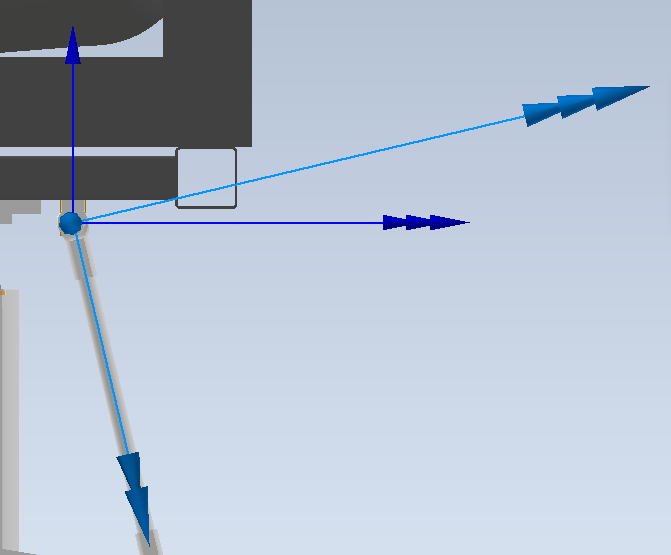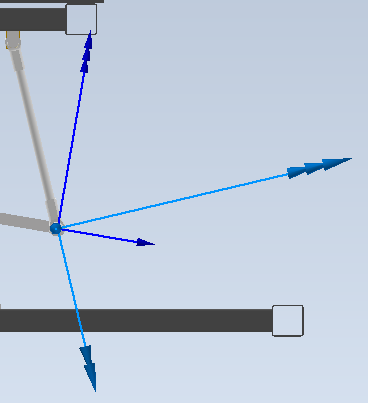

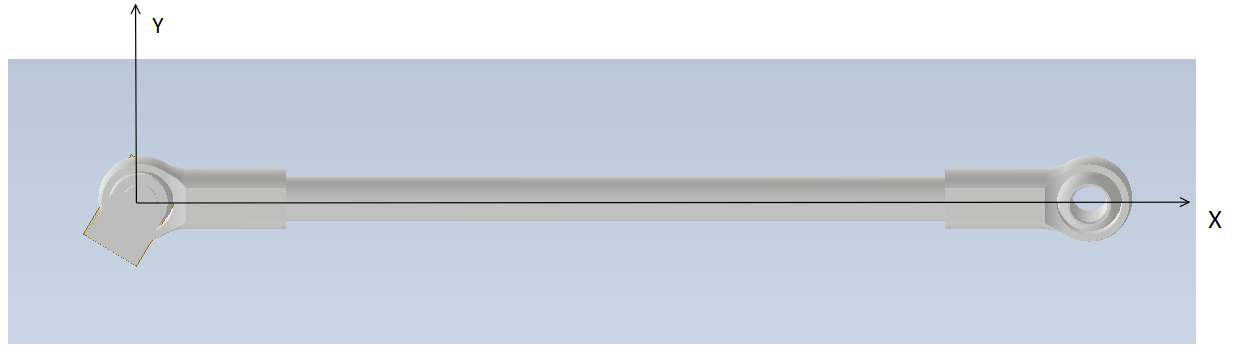

vectorTiempo=ManivelaBiela.T;


ManivelaBielaFx=ManivelaBiela.Fy;
ManivelaBielaFy=ManivelaBiela.Fz;
ManivelaBielaFz=ManivelaBiela.Fx;

SoporteBielaFx=SoporteBiela.Fy;
SoporteBielaFy=SoporteBiela.Fz;
SoporteBielaFz=SoporteBiela.Fx;

max(abs(SoporteBielaFx+ManivelaBielaFx))

ans = 1.5400

max(abs(ManivelaBielaFz))

ans = 0.1071

max(abs(ManivelaBielaFz))

ans = 0.1071

max(abs(SoporteBielaFy))

ans = 0.8904

max(abs(SoporteBielaFz))

ans = 0.0710

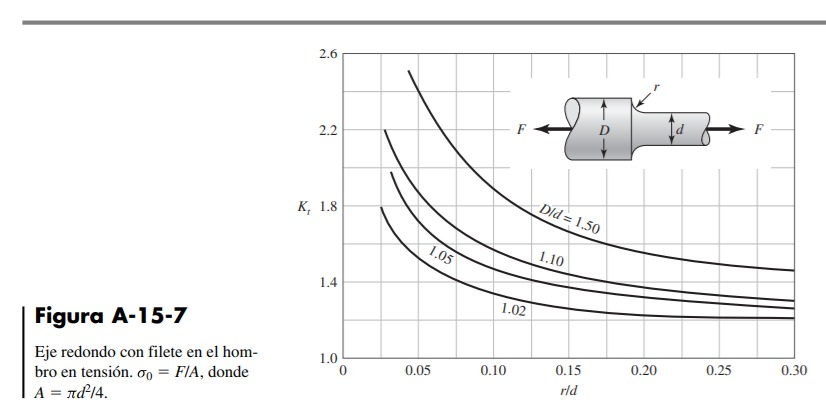

LargoTotal=0.42

LargoTotal = 0.4200

Diametro_menor=0.0254;

Diametro_menor_rosca=Diametro_menor-1.4*0.0254/14

Diametro_menor_rosca = 0.0229

Diametro_mayor=0.03175;

%1'-14


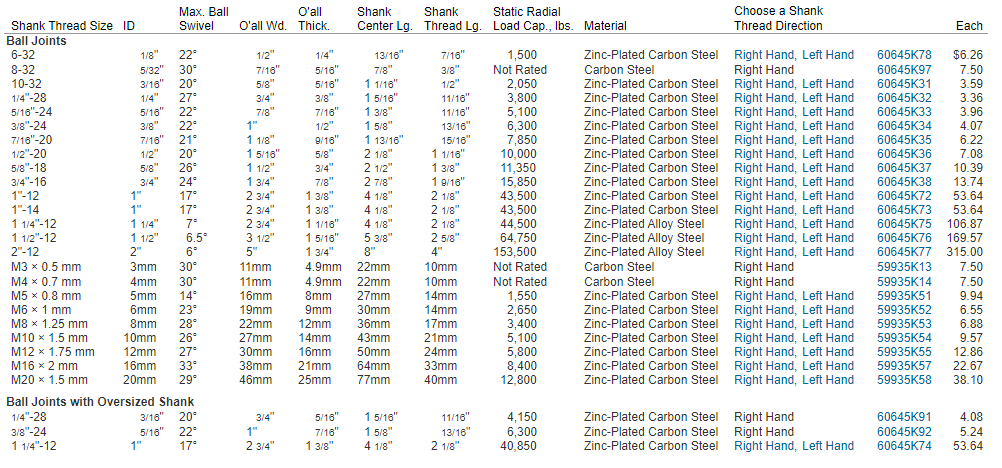

cargaMaximaLB=43500

cargaMaximaLB = 43500

cargaMaximaN=cargaMaximaLB*0.45

cargaMaximaN = 19575

max(SoporteBiela.F)

ans = 6.4128e+03



%r_filete=Diametro_menor*0.15
r_filete=0.0008

r_filete = 8.0000e-04


%1020 HR
Sut=380

Sut = 380

Sy=210

Sy = 210

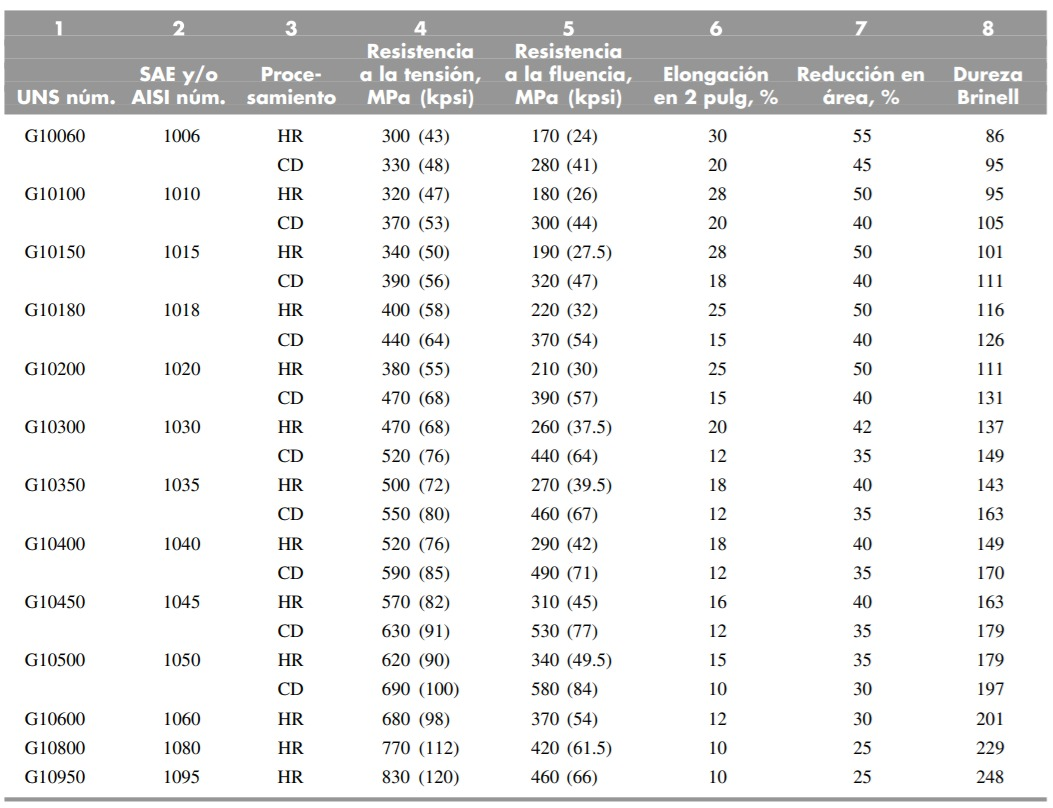

https://www.mcmaster.com/ball-joints/internally-threaded-ball-joint-rod-ends/


mega=1000000

mega = 1000000


A_t_menor=pi/4*Diametro_menor_rosca^2

A_t_menor = 4.1043e-04

A_t_mayor=pi/4*Diametro_mayor^2

A_t_mayor = 7.9173e-04

kt=ktHombro(Diametro_mayor,Diametro_menor_rosca,r_filete)

kt = 2.3713

kts=ktsHombro(Diametro_mayor,Diametro_menor_rosca,r_filete)

kts = 1.8160


neuberF=0.07

neuberF = 0.0700

neuberT=0.055

neuberT = 0.0550

radioMuesca=0.2 %inches

radioMuesca = 0.2000

qFlexion=1/(1+neuberF/sqrt(radioMuesca))

qFlexion = 0.8647

qTorsion=1/(1+neuberT/sqrt(radioMuesca))

qTorsion = 0.8905


Kf=1+qFlexion*(kt-1)

Kf = 2.1857

Kfs=1+qTorsion*(kts-1)

Kfs = 1.7266

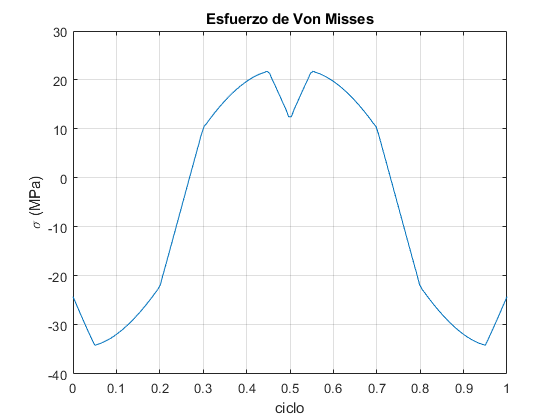



sigma_cargaAxial_soporte=Kf*SoporteBielaFx/A_t_menor;

plot(linspace(0,1,160),sigma_cargaAxial_soporte/1000000)
grid on
xlabel("ciclo")
ylabel("\sigma (MPa)")
title("Esfuerzo de Von Misses")



Fsup=4.51*(Sut)^(-0.265)

Fsup = 0.9344

Fcar=0.7

Fcar = 0.7000

Ftem=1

Ftem = 1

Ftam=1.189*(Diametro_menor_rosca*1000)^(-0.097)

Ftam = 0.8777

Fcon=0.814 % 99%

Fcon = 0.8140

SeSC=0.5*Sut

SeSC = 190

Se=SeSC*Fsup*Fcar*Ftem*Ftam*Fcon

Se = 88.7895


sigmaA=0.5.*abs(max(sigma_cargaAxial_soporte)-min(sigma_cargaAxial_soporte))/mega   %esfuerzo alternante

sigmaA = 27.9771

sigmaM=0.5.*abs(max(sigma_cargaAxial_soporte)+min(sigma_cargaAxial_soporte))/mega   %esfuerzo medio

sigmaM = 6.1735

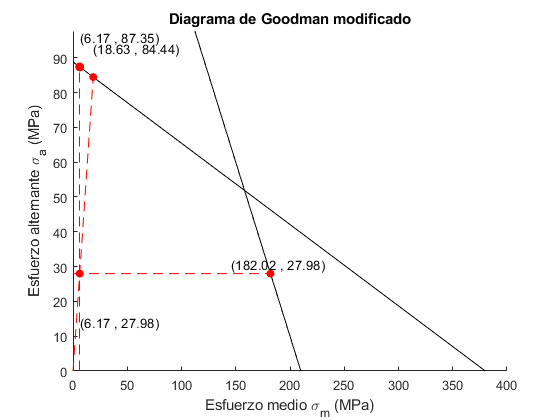

FS1 = 3.1221

FS2 = 3.0180

FS3 = 29.4844

FactorMinimo = 3.0180


FactorMinimo=diagramaGoodman(sigmaA,sigmaM,Sut,Sy,Se,true)

function [kt] = ktHombro(D,d,r)
    h=0.5*(D-d);
    var=sqrt(h/r);
    var2=2*h/D;
    c1=0.947+1.206*var-0.131*var^2;
    c2=0.022-3.405*var+0.915*var^2;
    c3=0.869+1.777*var-0.555*var^2;
    c4=-0.810+0.422*var-0.26*var^2;
    kt=c1+c2*var2+c3*var2^2+c4*var2^3;
end

function [kts] = ktsHombro(D,d,r)
    h=0.5*(D-d);
    var=sqrt(h/r);
    var2=2*h/D;
    c1=0.905+0.783*var-0.075*var^2;
    c2=-0.437-1.969*var+0.553*var^2;
    c3=1.557+1.073*var-0.578*var^2;
    c4=-1.061+0.171*var-0.086*var^2;
    kts=c1+c2*var2+c3*var2^2+c4*var2^3;
end

function FSMin=diagramaGoodman(EsigmaA,EsigmaM,ESut,ESy,ESe,tension)
syms x1 x2 x3 x4 x5
if(tension)
sigmaA=EsigmaA;
sigmaM=EsigmaM;
Sut=ESut;
Sy=ESy;
Se=ESe;
lineaF=@(x)    Sy-x;
goodManM=@(x)  Se-x.*Se./Sut;
lineaC=@(x)     sigmaA.*x./sigmaM;

Fr=sigmaA.*x1/sigmaM==Se-x1./Sut.*Se;
Fq= Sy-x2==sigmaA;
Fq2=Se-x5./Sut.*Se==sigmaA;

FSm=double(solve(Fr,x1));
FSy=double(solve(Fq,x2));
FSy2=double(solve(Fq2,x5));

if(FSy2<FSy)
    FSy=FSy2;
end

figure()
scatter(sigmaM,sigmaA,"r","filled")
hold on
fplot(lineaF,[0 Sy],"k")
fplot(goodManM,[0 Sut],"k")
fplot(lineaC,[0 FSm],"r--")
stem(sigmaM,goodManM(sigmaM),"r--","filled")
scatter(FSm,goodManM(FSm),"r","filled")
scatter(FSy,sigmaA,"r","filled")
fplot(sigmaA,[0 FSy],"r--")
scatter(sigmaM,sigmaA,"r","filled")
text(1.1*sigmaM,0.5*sigmaA,sprintf('(%.2f , %.2f)', sigmaM,sigmaA))
text(1.1*sigmaM,1.1*goodManM(sigmaM),sprintf('(%.2f , %.2f)', sigmaM,goodManM(sigmaM)))
text(FSm,1.1*goodManM(FSm),sprintf('(%.2f , %.2f)', FSm,goodManM(FSm)))
text(0.8*FSy,1.1*sigmaA,sprintf('(%.2f , %.2f)', FSy,sigmaA))
hold off
ylim([0 Se*1.1])
xlabel("Esfuerzo medio \sigma_m (MPa)")
ylabel("Esfuerzo alternante \sigma_a (MPa)")
title("Diagrama de Goodman modificado")
FS1=goodManM(sigmaM)/sigmaA
FS2=sqrt(FSm^2+goodManM(FSm)^2)/sqrt(sigmaM^2+sigmaA^2)
FS3=FSy/sigmaM
FSMin=min([FS1 FS2 FS3]);

else
    
    
sigmaA=EsigmaA;
sigmaM=-EsigmaM;
Sut=ESut;
Sy=ESy;
Se=ESe;
lineaF=@(x)    Sy+x;
goodManM=@(x)  Se;
lineaC=@(x)     sigmaA.*x./sigmaM;
Fr=sigmaA.*x1/sigmaM==Se;
Fq= Sy+x2==sigmaA;
Fc2=Se==Sy+x3;
FSm=double(solve(Fr,x1));
FSy=double(solve(Fq,x2));
FSn=double(solve(Fc2,x3));
figure()
scatter(sigmaM,sigmaA,"r","filled")
hold on
fplot(lineaF,[-Sy 0],"k")
fplot(goodManM,[FSn 0],"k")
fplot(lineaC,[FSm 0],"r--")
stem(sigmaM,goodManM(sigmaM),"r--","filled")
scatter(FSm,goodManM(FSm),"r","filled")
scatter(FSy,sigmaA,"r","filled")
fplot(sigmaA,[FSy 0],"r--")
scatter(sigmaM,sigmaA,"r","filled")
text(8*sigmaM,2*sigmaA,sprintf('(%.2f , %.2f)', sigmaM,sigmaA))
text(8*sigmaM,1.1*Se,sprintf('(%.2f , %.2f)', sigmaM,goodManM(sigmaM)))
text(1.1*FSm,1.1*Se,sprintf('(%.2f , %.2f)', FSm,goodManM(FSm)))
text(1.1*FSy,2*sigmaA,sprintf('(%.2f , %.2f)', FSy,sigmaA))
hold off
ylim([0 Se*1.2])
xlabel("Esfuerzo medio \sigma_m (MPa)")
ylabel("Esfuerzo alternante \sigma_a (MPa)")
title("Diagrama de Goodman modificado (Compresión)")
ax=gca;
ax.YAxisLocation = 'right';
FS1=Se/sigmaA
FS2=sqrt(FSm^2+Se^2)/sqrt(sigmaM^2+sigmaA^2)
FS3=FSy/sigmaM
FSMin=min([FS1 FS2 FS3]); 
end
end